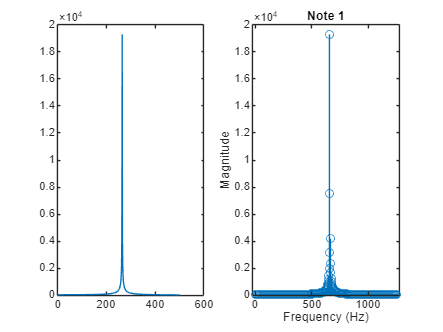

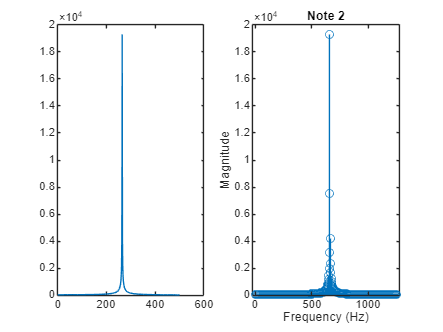

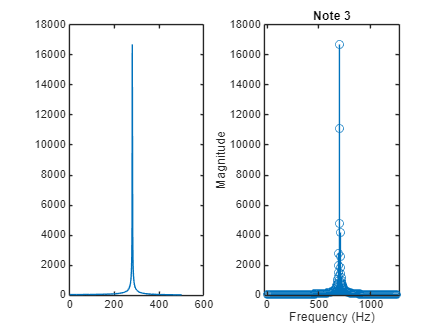

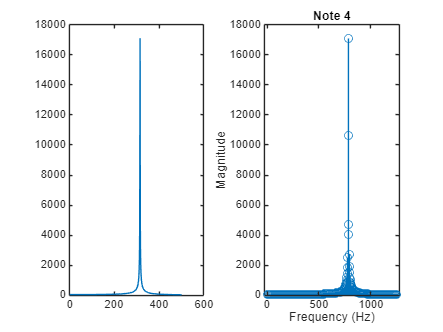

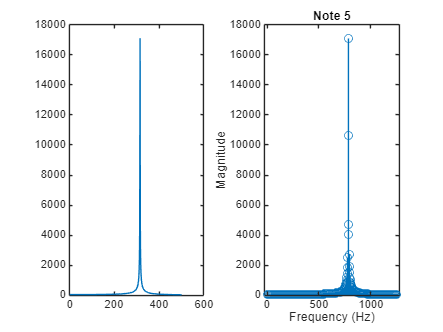

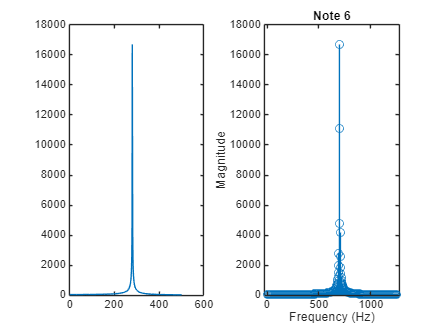

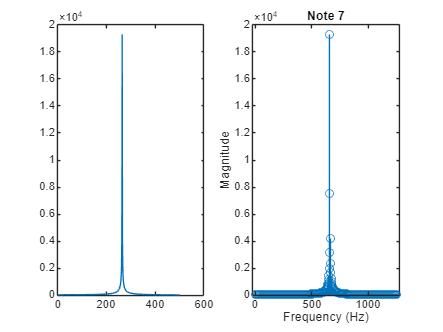

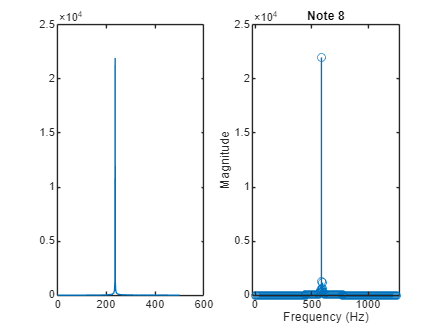

[y, Fs] = audioread('song.wav');

function coefficients = fourier_series_coe(x, n)
    L = length(x);
    coefficients=zeros(n,1);
    for k = 0:n-1
        for m = 1:L
            coefficients(k+1) = coefficients(k+1) + (44100/L) *(x(m) * exp(-1j*k*2*pi*(m-1) /L));
        end
    end
end

numOfnotes=round(length(y)/(0.4*Fs));
notes=cell(numOfnotes,1);
for m= 1:numOfnotes
     notes{m}=y((m-1)*(0.4*Fs +1)+1 : m*(0.4*Fs +1) , : );
end

coefficients=cell(numOfnotes,1);
dominant_freq=zeros(numOfnotes);
frequency= (1:500)*Fs / length(notes{m});

note_frequencies = [523.25, 587.33, 659.26, 698.46, 784.00]; 
note_names = {'C', 'D', 'E', 'F', 'G'}; 
identified_notes={};
for m = 1:numOfnotes

    coefficients{m}=fourier_series_coe(notes{m},500);
    
    % dominant frequency
    magnitudes = abs(coefficients{m}); 
    [~, dominant_idx] = max(magnitudes);
    dominant_freq(m) = ((dominant_idx - 1) * (44100/17641)); 
    
    figure;
    subplot(1,2,1);
    plot(abs(coefficients{m}))
    subplot(1,2,2);
    stem(frequency, abs(coefficients{m}));
    title(sprintf('Note %d', m));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

    [~, closest_idx] = min(abs(note_frequencies - dominant_freq(m)));
    identified_notes{end+1} = note_names{closest_idx};
end

for k=1:numOfnotes
    fprintf('note(%d):\n', k);
    disp(identified_notes(k));
end

note(1):


    {'E'}



note(2):


    {'E'}



note(3):


    {'F'}



note(4):


    {'G'}



note(5):


    {'G'}



note(6):


    {'F'}



note(7):


    {'E'}



note(8):


    {'D'}



note(9):


    {'C'}



note(10):


    {'C'}



note(11):


    {'D'}



note(12):


    {'E'}



note(13):


    {'E'}



note(14):


    {'D'}



note(15):


    {'D'}



note(16):


    {'D'}



note(17):


    {'E'}



note(18):


    {'E'}



note(19):


    {'F'}



note(20):


    {'G'}



note(21):


    {'G'}



note(22):


    {'F'}



note(23):


    {'E'}



note(24):


    {'D'}



note(25):


    {'C'}



note(26):


    {'C'}



note(27):


    {'D'}



note(28):


    {'E'}



note(29):


    {'D'}



note(30):


    {'C'}



note(31):


    {'C'}



note(32):


    {'C'}

